clear;
clc;

#### 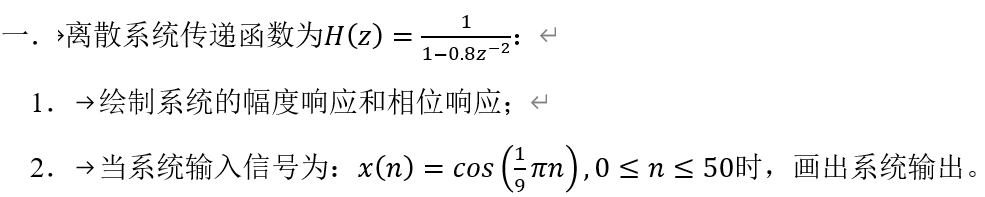

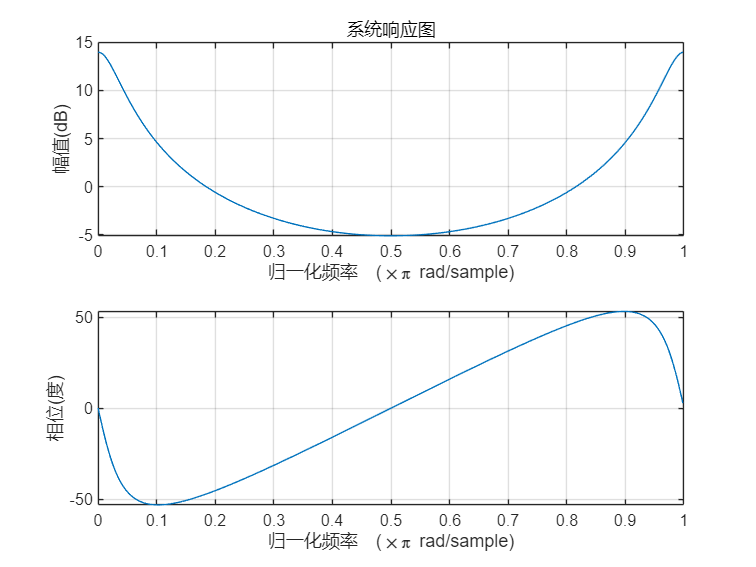

%%%%%%%%%%%%%%%%%%(1)%%%%%%%%%%%%%%%%%%
% 定义离散系统传递函数的分子和分母系数
b = 1;  % 分子系数
a = [1 0 -0.8];  % 分母系数

% 计算频率响应并绘图
figure(); 
freqz(b, a);  % 使用 freqz 函数计算并绘制系统的频率响应
title("系统响应图"); 

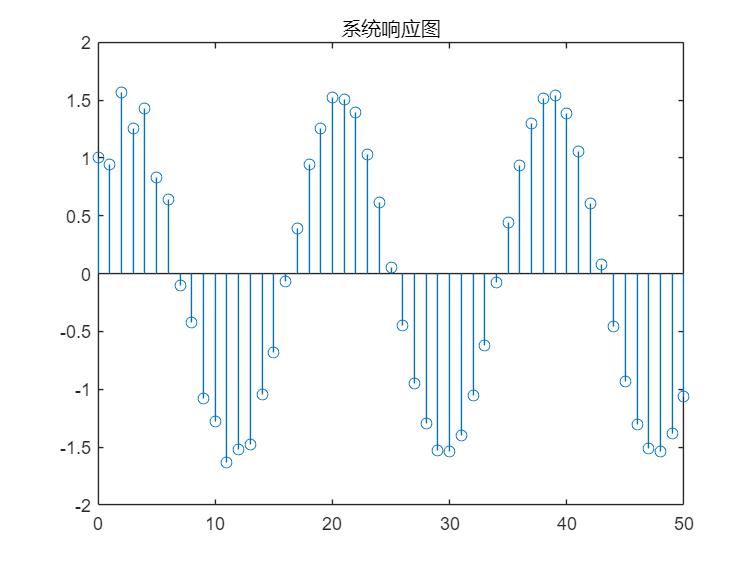

%%%%%%%%%%%%%%%%%%(2)%%%%%%%%%%%%%%%%%%
n = 0:1:50;  
h = impz(b, a, n);  % 使用 impz 函数计算系统的脉冲响应，n 指定了响应的长度
x = cos(1/9*pi*n);  
y = conv(h, x);  % 使用 conv 函数计算脉冲响应与输入信号的卷积，得到输出信号
Y = y(1:51);%截取规定时间范围内的信号
figure();  
stem(n,Y);  % 使用 stem 函数绘制离散时间信号 y
title("系统响应图");  

clear;
clc;

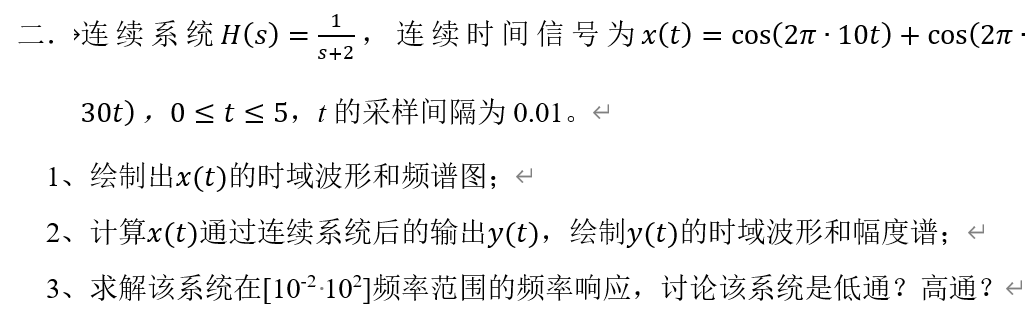

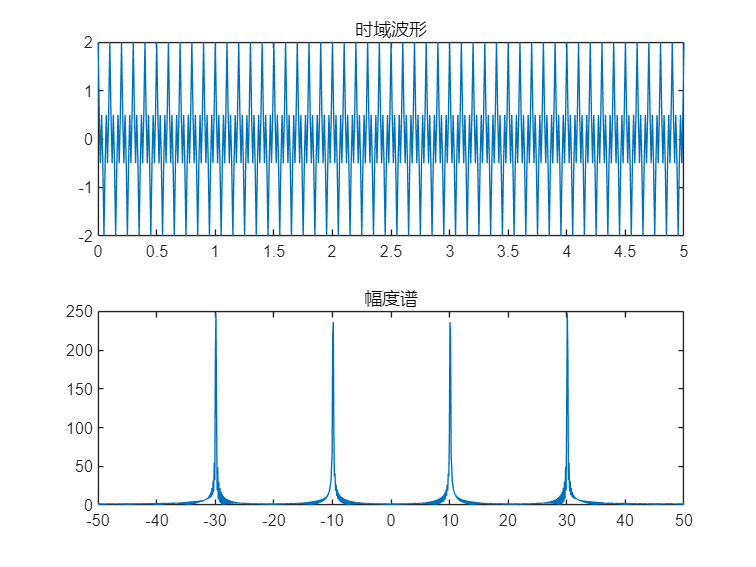

%%%%%%%%%%%%%%%%%(1)%%%%%%%%%%%%%%%%%
N = 1024;
fs = 100;% 定义采样频率
t = 0:1/fs:5;
n = -fs/2 + fs/N:fs/N:fs/2;
x = cos(2*pi*10*t) + cos(2*pi*30*t);
X = fft(x, N);% 对时域信号进行快速傅里叶变换（FFT）
X = fftshift(X);% 将FFT结果进行频移，使其以0为中心
figure();
subplot(2, 1, 1);
plot(t, x);
title('时域波形');
subplot(2, 1, 2);
plot(n, abs(X));
title('幅度谱');

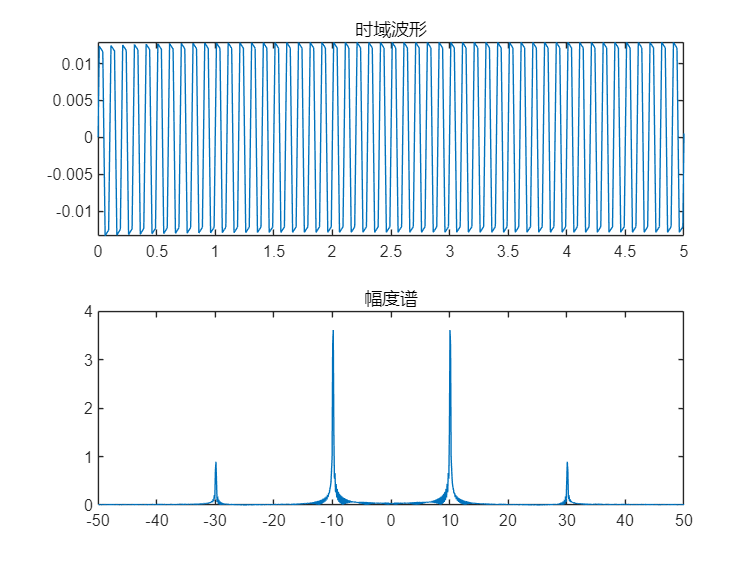

%%%%%%%%%%%%%%%%%(2)%%%%%%%%%%%%%%%%%
num = 1;
den = [1 2];% 定义系统的分子和分母系数
y = lsim(num, den, x, t);% 使用lsim函数模拟系统对x信号的响应
Y = fft(y, N);
Y = fftshift(Y);
figure();
subplot(2, 1, 1);
plot(t, y);
title('时域波形');
subplot(2, 1, 2);
plot(n, abs(Y));
title('幅度谱');

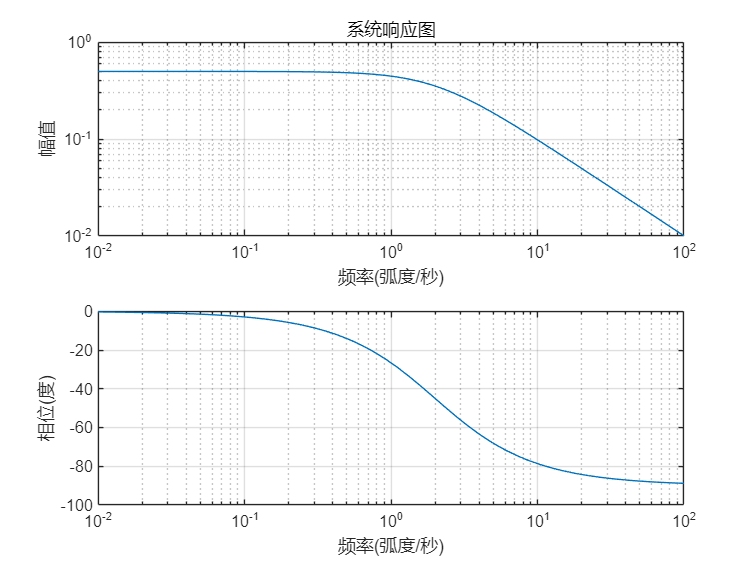

%%%%%%%%%%%%%%%%%(3)%%%%%%%%%%%%%%%%%
w = logspace(-2, 2);% 创建对数刻度的频率向量
figure();
freqs(num, den, w);
title("系统响应图");

**由幅度谱可知，此系统为低通系统。**

clear;
clc;

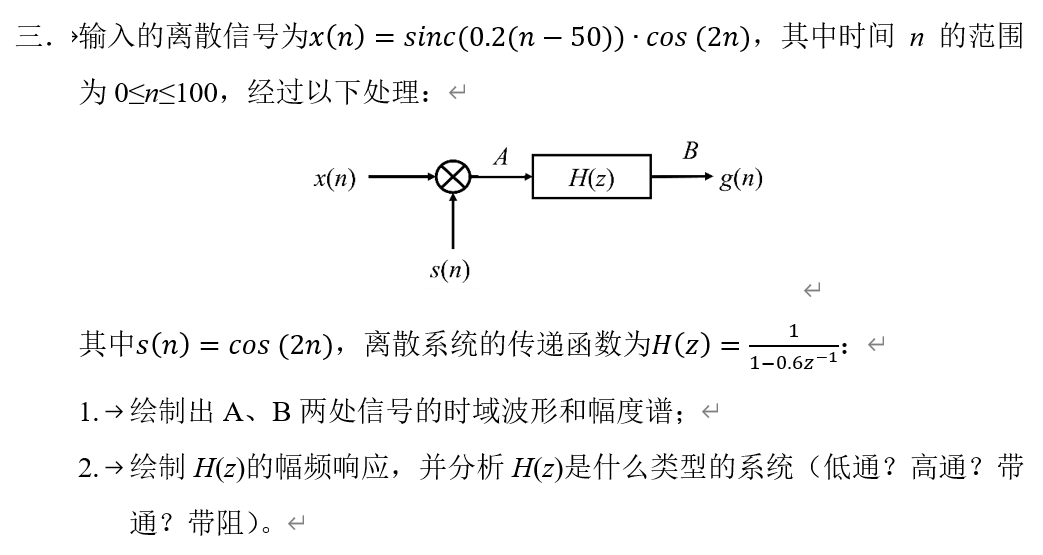

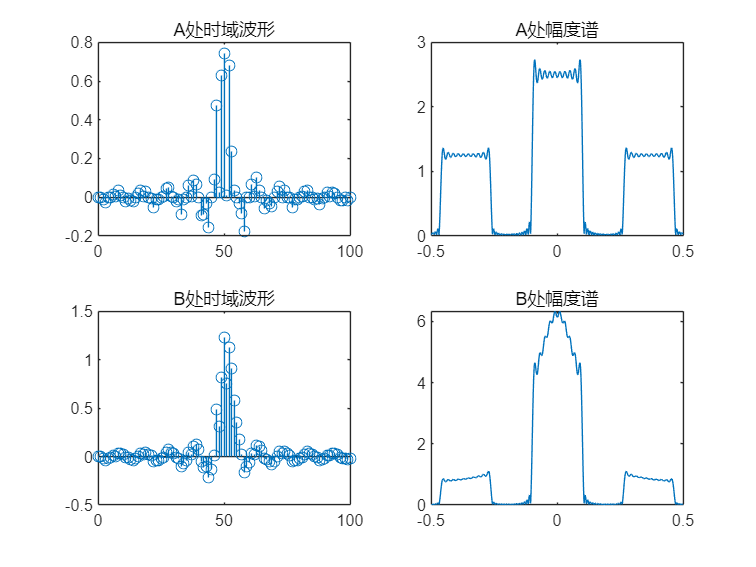

%%%%%%%%%%%%%%%%%(1)%%%%%%%%%%%%%%%%%
N = 1024;
n = 0:1:100;
fs = 1;% 定义采样频率
z = -fs/2 + fs/N:fs/N:fs/2;% 创建频率向量，从-fs/2到fs/2，步长为fs/N
x = sinc(0.2*(n-50)) .* cos(2*n);
s = cos(2*n);
a = x .* s;
A = fft(a, N);
A = fftshift(A);
num = 1;
den = [1 -0.6];
h = impz(num, den, n);% 使用impz函数计算系统的脉冲响应
b = conv(a, h);% 使用conv函数计算输入信号与脉冲响应的卷积，得到输出信号
bb =b (1:101);%截取规定时间范围内的信号
B = fft(b, N);
B = fftshift(B);
figure();
subplot(2, 2, 1);
stem(n, a);
title('A处时域波形');
subplot(2, 2, 2);
plot(z, abs(A));
title('A处幅度谱');
subplot(2, 2, 3);
stem(n,bb);
title('B处时域波形');
subplot(2, 2, 4);
plot(z, abs(B));
title('B处幅度谱');

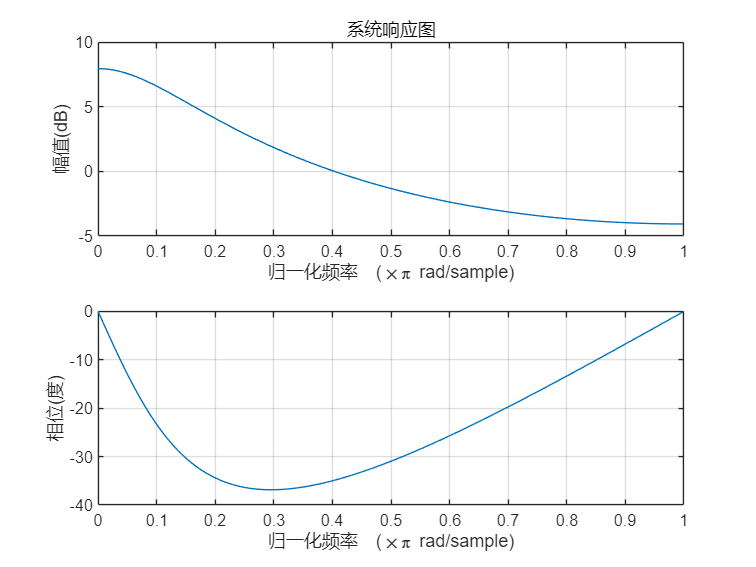

%%%%%%%%%%%%%%%%%(2)%%%%%%%%%%%%%%%%%%%
% 创建图形窗口并绘制系统的频率响应
figure();
freqz(num, den);
title("系统响应图");

**由幅度谱可知，此系统为低通系统。**